# Chapter 2 Exercises - MATLAB solutions

#### Exercise 7

Derive an explicit second-order Runge-Kutta method where $b_1 =\frac{1}{3}$`.`

% Define symbolic variables
syms a21 b2 c2

% Define b1 value
b1 = 1/3;

% Solve order conditions for a21, b2 and c2
eq1 = b1 + b2 - 1;
eq2 = c2 * b2 - 1/2;
eq3 = a21 - c2;

[a21, b2, c2] = solve(eq1, eq2, eq3)

$$a21 = \frac{3}{4}$$

$$b2 = \frac{2}{3}$$

$$c2 = \frac{3}{4}$$

#### Exercise 9

Derive a third-order explicit Runge-Kutta method where $c_2 = \frac{1}{2}$ and $c_3 = 1$.

% Define symbolic variables
syms a21 a31 a32 b1 b2 b3

% Define c values
c2 = 1/2;
c3 = 1;

% Define order conditions
eq1 = b1 + b2 + b3 == 1;
eq2 = b2 * c2 + b3 * c3 == 1/2;
eq3 = b2 * c2^2 + b3 * c3^2 == 1/3;
eq4 = b3 * a32 * c2 == 1/6;

% Define row sum conditions
eq5 = c2 == a21;
eq6 = c3 == a31 + a32;

% Solve order conditions
solve(eq1, eq2, eq3, eq4, eq5, eq6)

ans = struct with fields:
    a21: 1/2
    a31: -1
    a32: 2
     b1: 1/6
     b2: 2/3
     b3: 1/6


#### Exercise 10

Derive an explicit fourth-order Runge-Kutta method where $c_2 = \frac{1}{4}$, $c_3 = \frac{1}{2}$ and $c_4 = 1$. Hint: you will need to use the row sum conditions here.

% Define symbolic variables
syms a21 a31 a32 a41 a42 a43 b1 b2 b3 b4

% Define c values
c2 = 1/4;
c3 = 1/2;
c4 = 1;

% Solve for the b values
eq1 = b1 + b2 + b3 + b4 == 1;
eq2 = b2 * c2 + b3 * c3 + b4 * c4 == 1/2;
eq3 = b2 * c2^2 + b3 * c3^2 + b4 * c4^2 == 1/3;
eq4 = b2 * c2^3 + b3 * c3^3 + b4 * c4^3 == 1/4;

[b1, b2, b3, b4] = solve(eq1, eq2, eq3, eq4)

$$b1 = \frac{1}{6}$$

$$b2 = 0$$

$$b3 = \frac{2}{3}$$

$$b4 = \frac{1}{6}$$

% Solve for a32 a42 and a43
eq5 = b3 * a32 * c2 + b4 * a42 * c2 + b4 * a43 * c3 == 1/6;
eq6 = b3 * a32 * c3 * c2 + b4 * c4 * a42 * c2 + b4 * c4 * a43 * c3 == 1/8;
eq7 = b3 * a32 * c2^2 + b4 * a42 * c2^2 + b4 * a43 * c3^2 == 1/12;

[a32, a42, a43] = solve(eq5, eq6, eq7)

$$a32 = \frac{1}{2}$$

$$a42 = -2$$

$$a43 = 2$$

% Solve for a21, a31 and a41 using row sum conditions
eq9 = c2 - a21;
eq10 = c3 - a31 - a32;
eq11 = c4 - a41 - a42 - a43;

[a21, a31, a41] = solve(eq9, eq10, eq11)

$$a21 = \frac{1}{4}$$

$$a31 = 0$$

$$a41 = 1$$

#### Exercise 12

Define a Python or MATLAB function called `myrk2()` which uses the method from derived in exercise 7 to solve an initial value problem. Use your function to solve the following initial value problem using a step length $h=0.4$


$$y' = t - y, \qquad t \in [0, 2], \qquad y(0) = 1.$$


Present your solution as a plot of the numerical solutions against the exact solutions on the same set of axes.

% Define ODE function and exact solution
f = @(t, y) t - y;
exact = @(t) t + 2 * exp(-t) - 1;

% Define IVP parameters
tspan = [0, 2];     % boundaries of the t domain
y0 = 1;             % initial value of the solution
h = 0.4;            % step length

% Calculate the solution to the IVP
[t, y_myrk2] = solveIVP(f, tspan, y0, h, @myrk2);

% Calculate exact solution for plotting
texact = linspace(tspan(1), tspan(2), 200);
yexact = exact(texact);

% Print table of solution values (for loop is used to group print statements)
for i = 1 : 1
    fprintf('|  t   |     y     |   Exact   |\n|:----:|:---------:|:---------:|');
    for n = 1 : length(t)
        fprintf('\n| %4.2f | %9.6f | %9.6f |', t(n), y(n), exact(t(n)));
    end
end

|  t   |     y     |   Exact   |
|:----:|:---------:|:---------:|


| 0.00 |  1.000000 |  1.000000 |
| 0.40 |  0.943308 |  0.740640 |
| 0.80 |  0.893454 |  0.698658 |
| 1.20 |  0.849220 |  0.802388 |
| 1.60 |  0.810582 |  1.003793 |
| 2.00 |  0.777496 |  1.270671 |

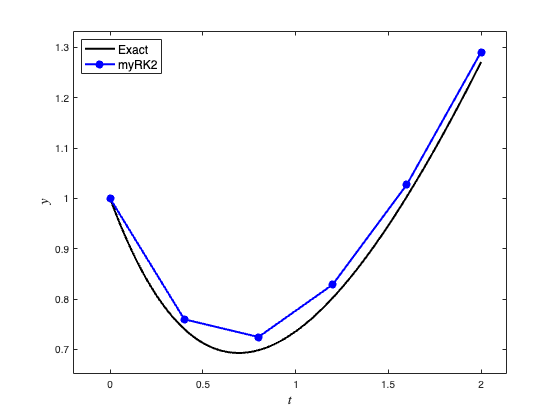


% Plot solution
plot(texact, yexact, 'k-', LineWidth=2)
hold on
plot(t, y_myrk2, 'b-o', LineWidth=2, MarkerFaceColor='b')
hold off
axis padded
xlabel('$t$', FontSize=14, Interpreter='latex')
ylabel('$y$', FontSize=14, Interpreter='latex')
legend('Exact', 'myRK2', Location='northwest', FontSize=12)

#### Exercise 13

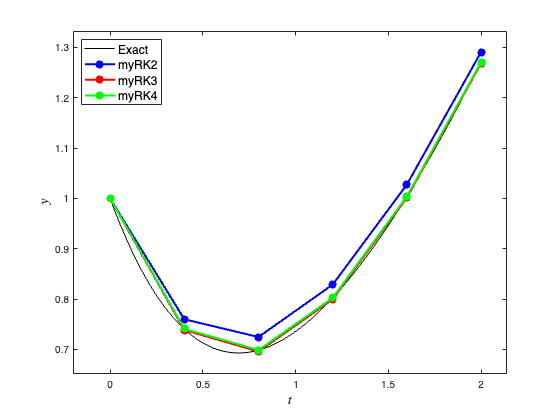

% Define ODE function and exact solution
f = @(t, y) t - y;
exact = @(t) t + 2 * exp(-t) - 1;

% Define IVP parameters
tspan = [0, 2];     % boundaries of the t domain
y0 = [1];           % initial value of the solution
h = 0.4;            % step length

% Calculate the solution to the IVP
[t, y_myrk2] = solveIVP(f, tspan, y0, h, @myrk2);
[t, y_myrk3] = solveIVP(f, tspan, y0, h, @myrk3);
[t, y_myrk4] = solveIVP(f, tspan, y0, h, @myrk4);

% Calculate exact solution for plotting
texact = linspace(tspan(1), tspan(2), 200);
yexact = exact(texact);

% Plot solution
plot(texact, yexact, 'k-', LineWidth=1)
hold on
plot(t, y_myrk2, 'b-o', LineWidth=2, MarkerFaceColor='b')
plot(t, y_myrk3, 'r-o', LineWidth=2, MarkerFaceColor='r')
plot(t, y_myrk4, 'g-o', LineWidth=2, MarkerFaceColor='g')
hold off
axis padded
xlabel('$t$', FontSize=14, Interpreter='latex')
ylabel('$y$', FontSize=14, Interpreter='latex')
legend('Exact', 'myRK2', 'myRK3', 'myRK4', Location='northwest', FontSize=12)

#### Exercise 12

% Calculate solution for decreasing step lengths
hvals = [0.4, 0.2, 0.1, 0.05, 0.025];
tval = 2;
E_myrk2 = [];
E_myrk3 = [];
E_myrk4 = [];
for h = hvals
    [t, y_myrk2] = solveIVP(f, tspan, y0, h, @myrk2);
    [t, y_myrk3] = solveIVP(f, tspan, y0, h, @myrk3);
    [t, y_myrk4] = solveIVP(f, tspan, y0, h, @myrk4);
    [~, idx] = min(abs(tval - t));
    E_myrk2 = [E_myrk2, abs(exact(tval) - y_myrk2(idx))];
    E_myrk3 = [E_myrk3, abs(exact(tval) - y_myrk3(idx))];
    E_myrk4 = [E_myrk4, abs(exact(tval) - y_myrk4(idx))];
end

% Output table of errors (for loop is used to group print statements)
for i = 1 : 1
    fprintf('|   t   |  myRK2   |  myRK4   |  myRK4   |')
    fprintf('|:-----:|:--------:|:--------:|:--------:|');
    for n = 1 : length(hvals)
        fprintf('\n| %1.3f | %1.2e | %1.2e | %1.2e |', hvals(n), E_myrk2(n), E_myrk3(n), E_myrk4(n))
    end
end

|   t   |  myRK2   |  myRK4   |  myRK4   |

|:-----:|:--------:|:--------:|:--------:|


| 0.400 | 2.01e-02 | 1.99e-03 | 1.61e-04 |
| 0.200 | 4.23e-03 | 2.12e-04 | 8.53e-06 |
| 0.100 | 9.74e-04 | 2.44e-05 | 4.90e-07 |
| 0.050 | 2.34e-04 | 2.93e-06 | 2.94e-08 |
| 0.025 | 5.75e-05 | 3.60e-07 | 1.80e-09 |

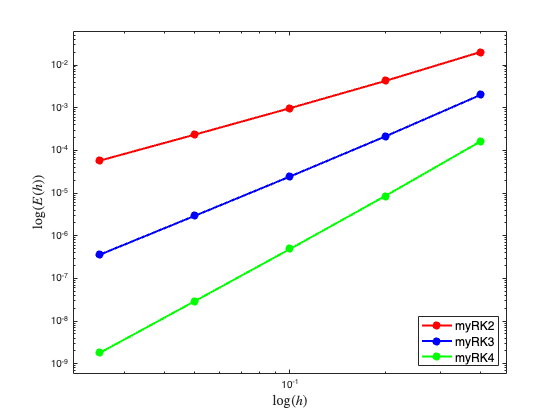

% Plot errors on a loglog scale
loglog(hvals, E_myrk2, 'ro-', MarkerFaceColor='r', LineWidth=2)
hold on
loglog(hvals, E_myrk3, 'bo-', MarkerFaceColor='b', LineWidth=2)
loglog(hvals, E_myrk4, 'go-', MarkerFaceColor='g', LineWidth=2)
hold off
axis padded
xlabel('$\log(h)$', FontSize=14, Interpreter='latex')
ylabel('$\log(E(h))$', FontSize=14, Interpreter='latex')
legend('myRK2', 'myRK3', 'myRK4', Location='southeast', FontSize=12)

#### Exercise 15

Combining Heun's method and Kutta's third-order method gives the following Butcher tableau for an embedded Runge-Kutta method


$$\begin{array}{c|ccc}
    0 & \\
    1/2 & 1/2 \\
    1 & -1 & 2 \\ \hline
    & 1/6 & 2/3 & 1/6 \\
    & 0 & 1 & 0 
\end{array}$$


where the first row of $b$ coefficients gives the third-order accurate solution and the second row gives the second-order accurate solution. Use this method to compute the solutions to the initial value problem from Exercise 12 using an initial step length of $h_0=0.4$ and an accuracy tolerance of $tol = 10^{-4}$. How many successful steps, failed steps and function evaluates were used?

% Define ODE function and exact solution
f = @(t, y) t - y;
exact = @(t) t + 2 * exp(-t) - 1;

% Define IVP parameters
tspan = [0, 2];     % boundaries of the t domain
y0 = 1;             % initial value of the solution
h0 = 0.4;           % step length
tol = 1e-4;         % accuracy tolerance

% Calculate the solution to the IVP
[t, y] = solveIVP_SSC(f, tspan, y0, h0,  @rk23, tol);

% Output number of successful steps
fprintf("%0i successful steps", length(t) - 1)

26 successful steps

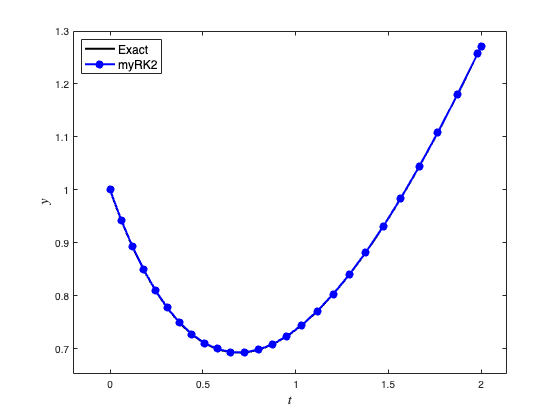


% Calculate exact solution for plotting
texact = linspace(tspan(1), tspan(2), 200);
yexact = exact(texact);

% Plot solution
plot(texact, yexact, 'k-', LineWidth=2)
hold on
plot(t, y, 'b-o', LineWidth=2, MarkerFaceColor='b')
hold off
axis padded
xlabel('$t$', FontSize=14, Interpreter='latex')
ylabel('$y$', FontSize=14, Interpreter='latex')
legend('Exact', 'myRK2', Location='northwest', FontSize=12)

## Functions

#### Single step solver

function [t, y] = solveIVP(f, tspan, y0, h, solver)

% Define t and y arrays
t = (tspan(1) : h : tspan(2));
y = zeros(length(t), length(y0));
y(1,:) = y0;

% Loop through the steps and calculate single step solver solution
for n = 1 : length(t) - 1
    y(n+1,:) = solver(f, t(n), y(n,:), h);
end

end

#### myRK2

function ynew = myrk2(f, t, y, h)

k1 = f(t, y);
k2 = f(t + 3/4 * h, y + 3/4 * h * k1);
ynew = y + h / 3 * (k1 + 2 * k2);

end

#### myRK3

function ynew = myrk3(f, t, y, h)

k1 = f(t, y);
k2 = f(t + 1/2 * h, y + 1/2 * h * k1);
k3 = f(t + h, y + h * (-k1 + 2 * k2));
ynew = y + h / 6 * (k1 + 4 * k2 + k3);

end

#### myRK4

function ynew = myrk4(f, t, y, h)

k1 = f(t, y);
k2 = f(t + 1/4 * h, y + 1/4 * h * k1);
k3 = f(t + 1/2 * h, y + 1/2 * h * k2);
k4 = f(t + h, y + h * (k1 - 2 * k2 + 2 * k3));
ynew = y + h / 6 * (k1 + 4 * k3 + k4);

end

#### IVP solver using adaptive step size control

function [t, y] = solveIVP_SSC(f, tspan, y0, h, solver, tol)

% Define t and y arrays
t = zeros(10000);
y = zeros(10000, length(y0));
t(1) = tspan(1);
y(1,:) = y0;

% Loop through the steps
n = 1;
while t(n) < tspan(2)
    
    % Calculate order p and p+1 solutions
    [yp1, yp, order] = solver(f, t(n), y(n,:), h);
    delta = max(abs(yp1 - yp));

    % Determine whether the step was successful or not
    if delta < tol
        y(n+1,:) = yp1;
        t(n+1) = t(n) + h;
        n = n + 1;
    end

    % Calculate new value of h (making sure not to exceed tmax)
    h = h * max(0.5, min(2, 0.9 * (tol / delta) ^ (1 / (order + 1))));
    h = min(h, tspan(2) - t(n));

end

% Remove unused entries from t and y
t(n+1:end) = [];
y(n+1:end,:) = [];

end

#### RK23

function [y3, y2, order] = rk23(f, t, y, h)

k1 = f(t, y);
k2 = f(t + 1/2 * h, y + 1/2 * h * k1);
k3 = f(t + h, y + h * (-k1 + 2 * k2));
y3 = y + h * (1/6 * k1 + 2/3 * k2 + 1/6 * k3);
y2 = y + h * k2;
order = 2;

end